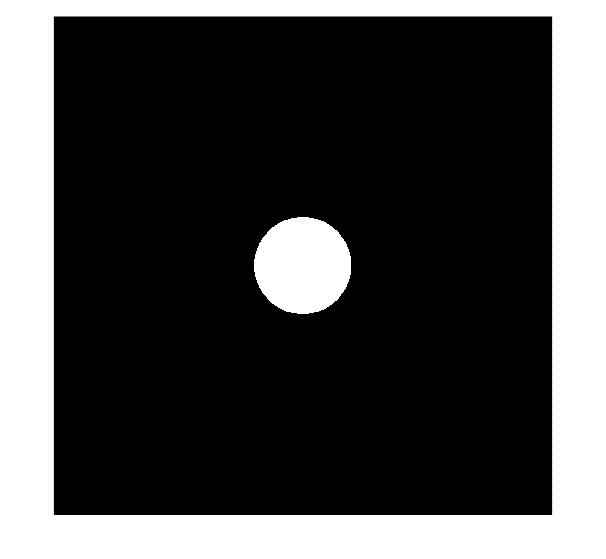

clc;
clear;
N = 1024;
I_64 = zeros(N, N);
[m, n] = meshgrid(linspace(-N/2, N/2 + 1, N));
r = input("input radius:");
x = input("input x coordinate of center:");
y = input("input y coordinate of center:");
D = ((m - x).^2 + (n - y).^2).^(1/2);
i = find(D <= r);
I_64(i) = 1;
imshow(I_64);

imwrite(I_64, "circle.png");

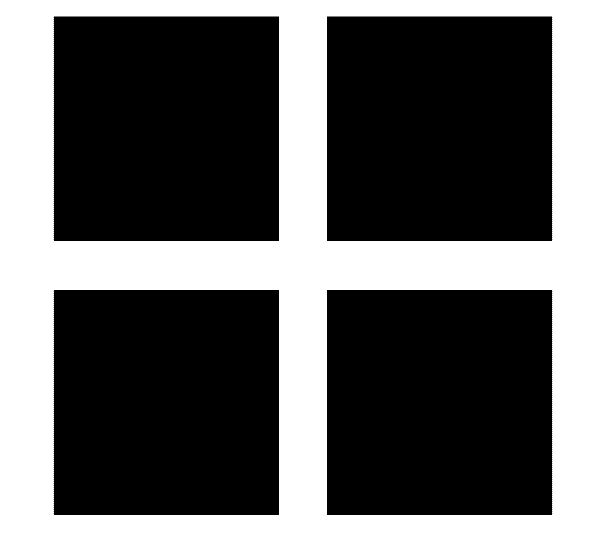

I_64 = zeros(N, N);
length = uint8(input("input length:"));
index = abs(m) <= length | abs(n) <= length;
I_64(index) = 1;
imshow(I_64);

imwrite(I_64, "cross slit.png");

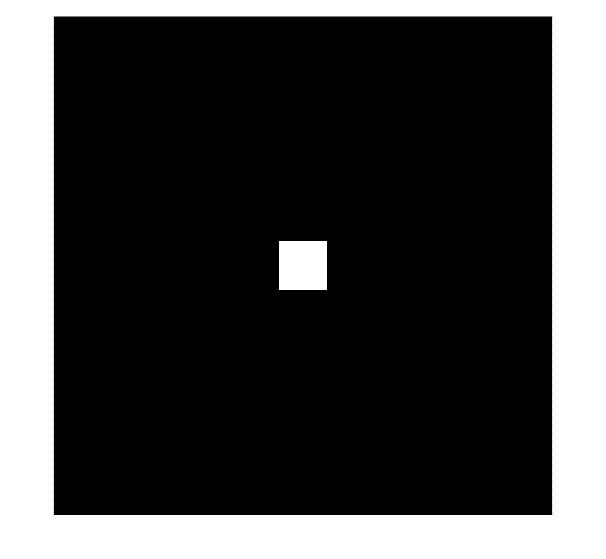

I_64 = zeros(N, N);
width = uint8(input("input the width of square:"));
index = find(abs(m) <= width/2 & abs(n) <= width/2);
I_64(index) = 1;
imshow(I_64);

imwrite(I_64, "square.png");

img_a = imread("circle.png");
grid on;

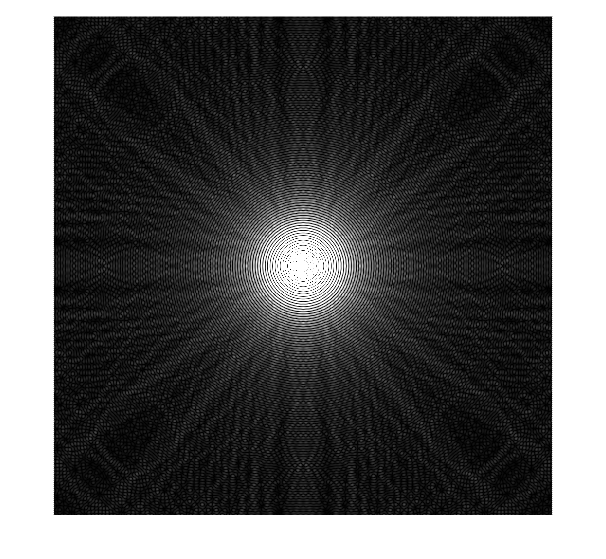

% img_gray = rgb2gray(img_a);
img_gray_a = double(img_a);

afft = fft2(img_gray_a);
afftI = fftshift(afft);
% RR = real(afftI);
% II = imag(afftI);

amp = abs(afftI);
normalized = ((amp - min(min(amp)))./(max(max(amp)) - min(min(amp)))) * 255;
figure(1);
imshow(normalized);

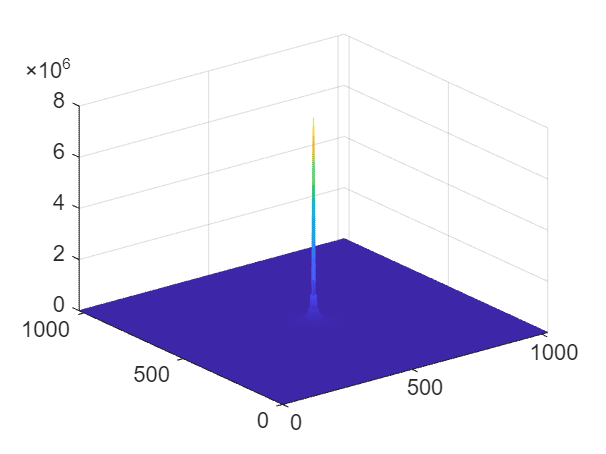


[sz_y, sz_x] = size(amp);
[x, y] = meshgrid(1:sz_y, 1:sz_x);
figure(2);
mesh(x, y, amp);

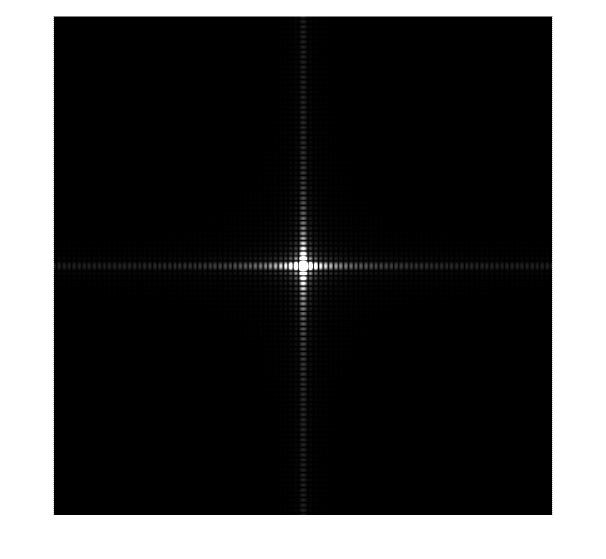

img_b = imread("cross slit.png");
% img_gray_b = rgb2gray(img_b);
img_gray_b = double(img_b);

afft = fft2(img_gray_b);
afftI = fftshift(afft);
% RR = real(afftI);
% II = imag(afftI);

amp = abs(afftI);
normalized = ((amp - min(min(amp)))./(max(max(amp)) - min(min(amp)))) * 255;
figure(3);
imshow(normalized);

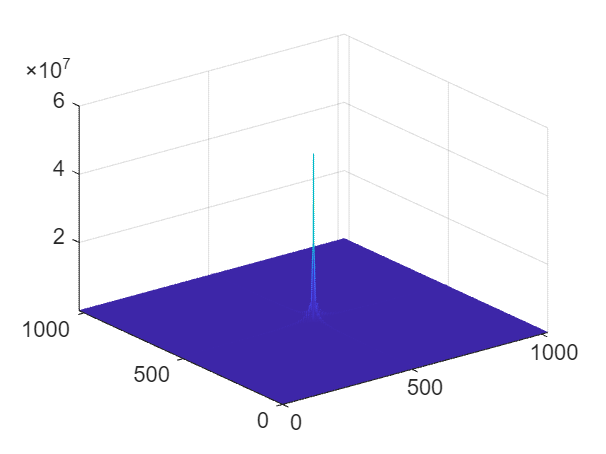


[sz_y, sz_x] = size(amp);
[x, y] = meshgrid(1:sz_y, 1:sz_x);
figure(4);
mesh(x, y, amp);

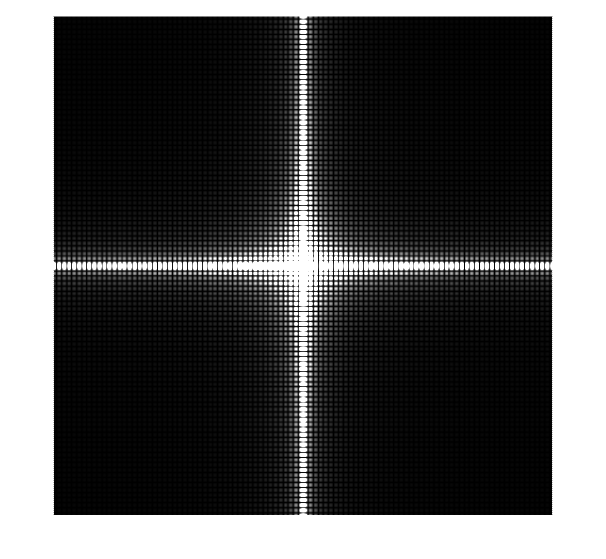

img_c = imread("square.png");
% img_gray_c = rgb2gray(img_c);
img_gray_c = double(img_c);

afft = fft2(img_gray_c);
afftI = fftshift(afft);
% RR = real(afftI);
% II = imag(afftI);

amp = abs(afftI);
normalized = ((amp - min(min(amp)))./(max(max(amp)) - min(min(amp)))) * 255;
figure(5);
imshow(normalized);

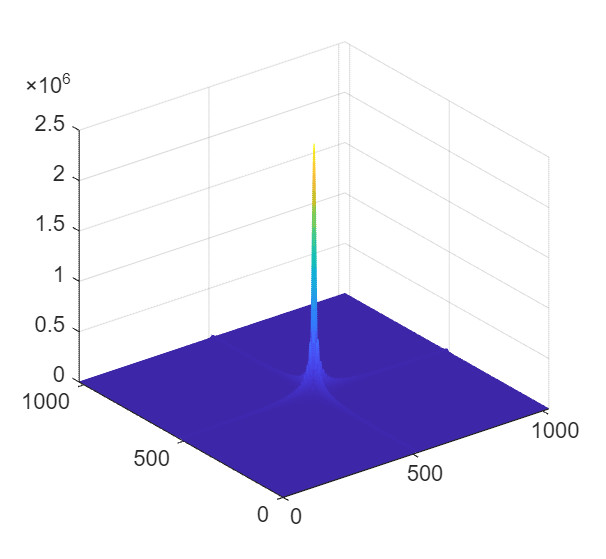


[sz_y, sz_x] = size(amp);
[x, y] = meshgrid(1:sz_y, 1:sz_x);
figure(6);
mesh(x, y, amp);